# Exercise 2

## Obstacle Potentials

### About This Exercise

So far, you've developed control methods that drive the robot straight towards the goal. However, what if we know there is an obstacle between the robot and the goal? Going back to the sledding analogy, if there was a tree between us and the bottom of the hill, we would want to adjust our control to avoid it. We can build a potential function for our tree, or any obstacle, where it grows very quickly as we approach the edges of the obstacle. We are basically building a very steep hill right around the tree that will repel the sled if it gets too close.

The nice thing about potential functions is that we can simply add them together and use the gradient of the summed potential function to command our robot. In this exercise, you will first write a potential function for an obstacle. Then you will visualize how the potential function changes as you add the obstacle potential to your previous bowl potential. Then you will simulate a holonomic robot as it navigates toward the goal around an obstacle using the combined potential functions.

**By the end of this exercise, you'll be able to: **

- **Move a robot towards a goal while avoiding obstacles using obstacle potentials.**

### Towering monolith

First we need to write functions that will calculate the potential and gradients at input points for a given polygon representing the boundary of an obstacle. 

[► Write the obstacle potential function](matlab:open('./obstaclePotential.mlx'))

Once complete, follow the section below to calculate and visualize the potential function being added to the quadratic potential function from the previous exercise.

#### Calculate and Visualize

- Set the goal and parameters C and Q.

goal_x = 0;
goal_y = 0;
C = 0.3;
Q = 8.5;

- Create a polygon that approximates a circle centered at [2,2]. The polygon's first column contains the x coordinates and the second contains the y coordinates. 

center = [2,2]

center =      2     2


radius = 0.5;
th = linspace(0,2*pi,21)

th =          0    0.3142    0.6283    0.9425    1.2566    1.5708    1.8850    2.1991    2.5133    2.8274    3.1416    3.4558    3.7699    4.0841    4.3982    4.7124    5.0265    5.3407    5.6549    5.9690    6.2832


poly = [center(1)+radius*cos(th(1:end-1)'),center(2)+radius*sin(th(1:end-1)')];

- Now we will use both the quadraticPotential and obstaclePotential functions to create two potentials.

dx = 0.1;
x = -4:dx:4;
y = x;
[X,Y] = meshgrid(x,y);
[Ugoal, dUdxgoal, dUdygoal] = quadraticPotential(X,Y,[goal_x,goal_y],C);
[Uobs,dUdxobs,dUdyobs] = obstaclePotential(X,Y,poly,C,Q);

- Combine potentials

U = Ugoal + Uobs;
dUdx = dUdxgoal + dUdxobs;
dUdy = dUdygoal + dUdyobs;

- Plot potentials

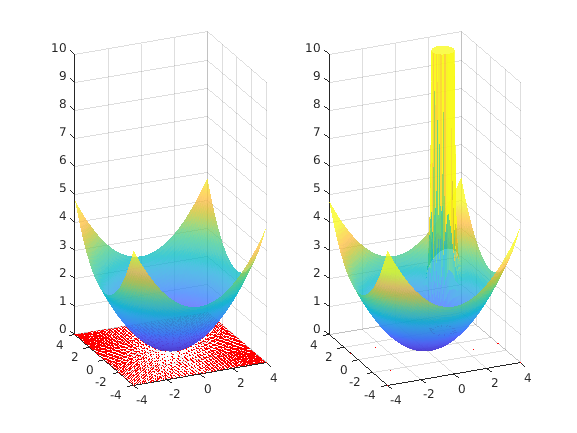

[indx, indy] = plotPotentials(dUdxgoal, dUdygoal, X, Y, Ugoal,U, dUdx, dUdy);

This function will animate the robot using the control derived from the potential function. What happens if the obstacle is directly inbetween the start and goal position (set the start_x and start_y = 3)

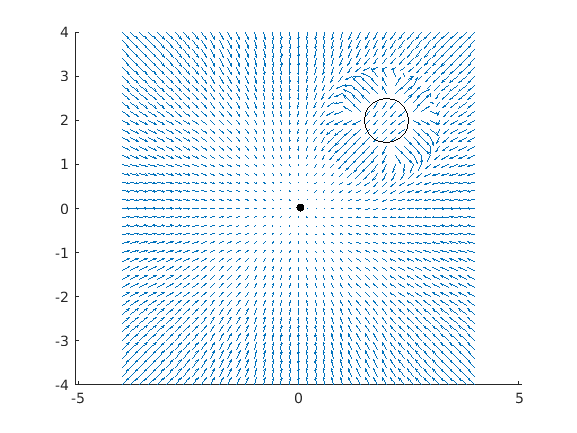

start_x = 3.8;
start_y = 3.5;
animate_robot(X, indx, indy, Y, dUdx, dUdy, start_x, start_y, goal_x, goal_y, C,poly);

### Finished!

Now that you have built a general function for a goal potential and an obstacle potential, you have the ability to combine them to drive the robot towards a goal while avoiding obstacles. In the next exercises, we will look at some of the issues that can arise from this method as we add more obstacles.

% This code is for the visualization and plotting. 
% PLEASE DO NOT MODIFY THIS CODE.

function [indx, indy] = plotPotentials(dUdx, dUdy, X, Y, Ugrid,Ugrid2, dUdx2, dUdy2)
figure
subplot(1,2,1)
hold off
surf(X,Y,Ugrid,'EdgeColor',"none",'FaceAlpha',0.75)
hold on
indx = 1:2:size(X,2);
indy = 1:2:size(Y,1);
quiver(X(indx,indy),Y(indx,indy),-1*dUdx(indx,indy),-1*dUdy(indx,indy),'r')
axis([-4 4 -4 4 0 10])
subplot(1,2,1)
view([-23.9 11.1])

subplot(1,2,2)
hold off
surf(X,Y,Ugrid2,"EdgeColor",'none','FaceAlpha',0.75)
caxis([0 4])
hold on
quiver(X(indx,indy),Y(indx,indy),-1*dUdx2(indx,indy),-1*dUdy2(indx,indy),'r')
axis([-4 4 -4 4 0 10])
subplot(1,2,2)
view([-23.9 11.1])
end

function animate_robot(X, indx, indy, Y, dUdx, dUdy, start_x, start_y, goal_x, goal_y, C,poly)
dt = 0.1;
figure

hold on
dxp = dUdx;
dxp(dxp>1) = 1;
dxp(dxp<-1) = -1;
dyp = dUdy;
dyp(dyp>1) = 1;
dyp(dyp<-1) = -1;
quiver(X(indx,indy),Y(indx,indy),-1*dxp(indx,indy),-1*dyp(indx,indy))
h1 = plot(start_x,start_y,'.k','MarkerSize',20);
plot([poly(:,1); poly(1,1)],[poly(:,2); poly(1,2)],'k-')
axis equal

pose = [start_x,start_y];

goal = [goal_x,goal_y];
tic
while (norm(pose-goal) > 0.05) && toc < 20
    [~, u1x, u1y]  =  obstaclePotential(pose(1),pose(2),poly,C,1);
    [~, u2x, u2y]  =  quadraticPotential(pose(1),pose(2),goal,C);
    
    pose = pose + [-u1x-u2x,-u1y-u2y]*dt;
    h1.XData = pose(1);
    h1.YData = pose(2);

    drawnow limitrate
    pause(dt)
end
drawnow
end